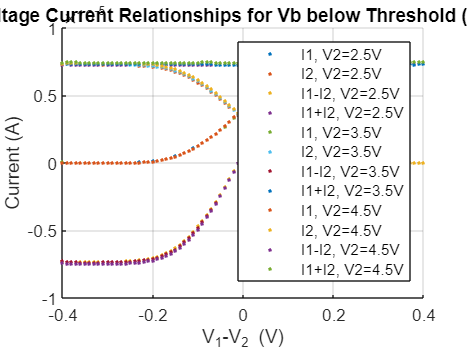

%Part 1
load("0.7V_bias_below_threshold\2.5V gate\Ch1\Idrain.mat")
load("0.7V_bias_below_threshold\2.5V gate\Ch1\Vgate.mat")
Ch1Idrain2_5=Idrain;
Ch1Vgate2_5=Vgate;
load("0.7V_bias_below_threshold\2.5V gate\Ch2\Idrain.mat")
load("0.7V_bias_below_threshold\2.5V gate\Ch2\Vgate.mat")
Ch2Idrain2_5=Idrain;
Ch2Vgate2_5=Vgate;
load("0.7V_bias_below_threshold\3.5V gate\Ch1\Idrain.mat")
load("0.7V_bias_below_threshold\3.5V gate\Ch1\Vgate.mat")
Ch1Idrain3_5=Idrain;
Ch1Vgate3_5=Vgate;
load("0.7V_bias_below_threshold\3.5V gate\Ch2\Idrain.mat")
load("0.7V_bias_below_threshold\3.5V gate\Ch2\Vgate.mat")
Ch2Idrain3_5=Idrain;
Ch2Vgate3_5=Vgate;
load("0.7V_bias_below_threshold\4.5V gate\Ch1\Idrain.mat")
load("0.7V_bias_below_threshold\4.5V gate\Ch1\Vgate.mat")
Ch1Idrain4_5=Idrain;
Ch1Vgate4_5=Vgate;
load("0.7V_bias_below_threshold\4.5V gate\Ch2\Idrain.mat")
load("0.7V_bias_below_threshold\4.5V gate\Ch2\Vgate.mat")
Ch2Idrain4_5=Idrain;
Ch2Vgate4_5=Vgate;

clf
hold on
plot_characteristics(Ch1Idrain2_5,Ch2Idrain2_5,Vgate)
plot_characteristics(Ch1Idrain3_5,Ch2Idrain3_5,Vgate)
plot_characteristics(Ch1Idrain4_5,Ch2Idrain4_5,Vgate)
legend("I1, V2=2.5V","I2, V2=2.5V","I1-I2, V2=2.5V","I1+I2, V2=2.5V","I1, V2=3.5V","I2, V2=3.5V","I1-I2, V2=3.5V","I1+I2, V2=3.5V","I1, V2=4.5V","I2, V2=4.5V","I1-I2, V2=4.5V","I1+I2, V2=4.5V")
title("Voltage Current Relationships for Vb below Threshold (0.5V)")
xlabel("V_1-V_2 (V)")
ylabel("Current (A)")
grid on
hold off

%part 2
clf
hold on
gm(Ch1Idrain2_5,Ch2Idrain2_5,Vgate,2.5)

mmax = 5.7115e-05

gm(Ch1Idrain3_5,Ch2Idrain3_5,Vgate,3.5)

mmax = 5.8238e-05

gm(Ch1Idrain4_5,Ch2Idrain4_5,Vgate,4.5)

mmax = 5.9857e-05

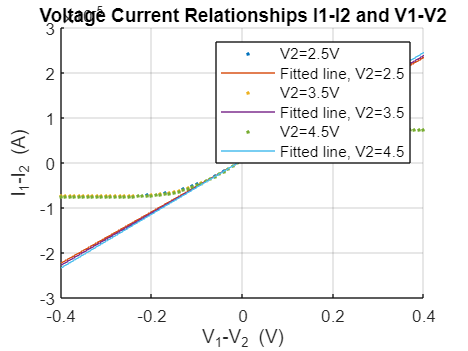

title("Voltage Current Relationships I1-I2 and V1-V2")
xlabel("V_1-V_2 (V)")
ylabel("I_1-I_2 (A)")
grid on
lgd = legend;
%legend("I1-I2 V=2.5","Fit V=2.5","I1-I2 V=3.5","Fit V=3.5","I1-I2 V=4.5","Fit V=4.5")
hold off

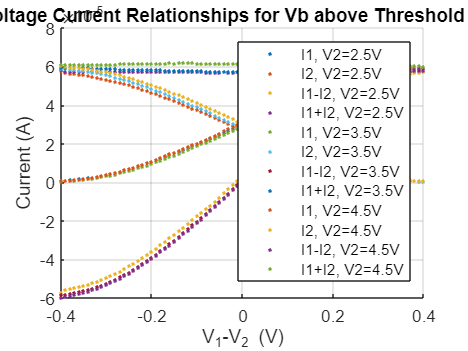

%Part 3
clear
load("1V_bias_above_threshold\2.5V gate\Ch1\Idrain.mat")
load("1V_bias_above_threshold\2.5V gate\Ch1\Vgate.mat")
Ch1Idrain2_5=Idrain;
Ch1Vgate2_5=Vgate;
load("1V_bias_above_threshold\2.5V gate\Ch2\Idrain.mat")
load("1V_bias_above_threshold\2.5V gate\Ch2\Vgate.mat")
Ch2Idrain2_5=Idrain;
Ch2Vgate2_5=Vgate;
load("1V_bias_above_threshold\3.5V gate\Ch1\Idrain.mat")
load("1V_bias_above_threshold\3.5V gate\Ch1\Vgate.mat")
Ch1Idrain3_5=Idrain;
Ch1Vgate3_5=Vgate;
load("1V_bias_above_threshold\3.5V gate\Ch2\Idrain.mat")
load("1V_bias_above_threshold\3.5V gate\Ch2\Vgate.mat")
Ch2Idrain3_5=Idrain;
Ch2Vgate3_5=Vgate;
load("1V_bias_above_threshold\4.5V gate\Ch1\Idrain.mat")
load("1V_bias_above_threshold\4.5V gate\Ch1\Vgate.mat")
Ch1Idrain4_5=Idrain;
Ch1Vgate4_5=Vgate;
load("1V_bias_above_threshold\4.5V gate\Ch2\Idrain.mat")
load("1V_bias_above_threshold\4.5V gate\Ch2\Vgate.mat")
Ch2Idrain4_5=Idrain;
Ch2Vgate4_5=Vgate;
%Recollect above threshold 3.5 volts recollect channel 1
%Recollection Ch2Idrain2_5 Ch2Idrain3_5 they are the same
clf
hold on
plot_characteristics(Ch1Idrain2_5,Ch2Idrain2_5,Vgate)
plot_characteristics(Ch1Idrain3_5,Ch2Idrain3_5,Vgate) %This is wrong
plot_characteristics(Ch1Idrain4_5,Ch2Idrain4_5,Vgate)
legend("I1, V2=2.5V","I2, V2=2.5V","I1-I2, V2=2.5V","I1+I2, V2=2.5V","I1, V2=3.5V","I2, V2=3.5V","I1-I2, V2=3.5V","I1+I2, V2=3.5V","I1, V2=4.5V","I2, V2=4.5V","I1-I2, V2=4.5V","I1+I2, V2=4.5V")
title("Voltage Current Relationships for Vb above Threshold (1V)")
xlabel("V_1-V_2 (V)")
ylabel("Current (A)")
grid on
hold off

function plot_characteristics(I1,I2,Vdm)
plot(Vdm,I1,".")
plot(Vdm,I2,".")
plot(Vdm,I1-I2,".")
plot(Vdm,I1+I2,".")
end
function gm(I1,I2,gate,v2)
plot(gate,I1-I2,".",'DisplayName',"V2="+num2str(v2)+"V")
[first, last, mmax, bmax, Nmax]=linefit(gate,I1-I2, 5e-4);
x=linspace(-0.4,0.4);
plot(x,mmax*x+bmax,'DisplayName',"Fitted line, V2="+num2str(v2))
mmax
end